# Matlab Mincer Wage Earnings Equation with Experience, Education and Gamma Shocks

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Define a Wage Equation with Partial Income for Part-time Workss

Individuals might work part or full time. Define a mincer wage equation that is a function of experienc, education and other individual characteristics. This is partly based on the wage equation from [Hai and Heckman (2017)](https://www.sciencedirect.com/science/article/abs/pii/S1094202517300029).

First define parameters.

% cognitive and non-cognitive latent types
theta_cogntv = 0.1;
theta_noncog = 0.1;
% parameters mapping latent types to wage
COEF_alpha_cog_wage_hsh = 0.0529;
COEF_alpha_cog_wage_clg = 0.0529;
COEF_alpha_cog_wage_grd = 0.1433;
COEF_alpha_ncg_wage_hsh = 0.0275;
COEF_alpha_ncg_wage_clg = 0.0512;
COEF_alpha_ncg_wage_grd = 0.0892;
% Experience
COEF_beta_psi_0 = 1.8884;
COEF_beta_psi_k = 0.0767;
COEF_beta_psi_kk = -0.2683;
% Education
COEF_beta_psi_e0 = 0.0465;
COEF_beta_w_e_1 = 0.1432;
COEF_beta_w_e_2 = 0.1435;
COEF_beta_w_e_3 = 0.2806;
% for part time
COEF_beta_w_part_0 = -0.0082;
COEF_beta_w_part_1 = -0.4863;

Second define the log wage equation. This wage equation is a function of the parameters defined above, and also Education (ED), experience (EX) and the wage shcok (EPS_w).

% Log of wage
f_log_psi = @(ED, EX, EPS_w) ...
    ((COEF_alpha_cog_wage_hsh.*theta_cogntv + COEF_alpha_ncg_wage_hsh.*theta_noncog).*(ED < 12) ...
    + (COEF_alpha_cog_wage_clg.*theta_cogntv + COEF_alpha_ncg_wage_clg.*theta_noncog).*(ED >= 12).*(ED < 16) ...
    + (COEF_alpha_cog_wage_grd.*theta_cogntv + COEF_alpha_ncg_wage_grd.*theta_noncog).*(ED >= 16) ...
    + COEF_beta_psi_0 ...
    + COEF_beta_psi_k.*EX ...
    + COEF_beta_psi_kk.*(EX.^2/100) ...
    + COEF_beta_psi_e0.*(ED - 12) ...
    + COEF_beta_w_e_1.*(ED == 12) ...
    + COEF_beta_w_e_2.*(ED > 12).*(ED < 16) ...
    + COEF_beta_w_e_3.*(ED >= 16) ...
    + EPS_w);

Third, define wage, which might differ depending on work status as well as schooling status. D_e is schooling or not, which can take values of 0 or 1. D_k is work status, which can take values or 0, 0.5 (part-time work) and 1 (full-time work).

% Per hour wage considering part time, part time wage differ if also schooling
f_hr_wage = @(D_e, D_k, ED, EX, EPS_w) ...
    exp(f_log_psi(ED, EX, EPS_w)).*exp((D_k==0.5).*(COEF_beta_w_part_0 + COEF_beta_w_part_1.*D_e));
% Total wage
f_wage = @(D_e, D_k, ED, EX, EPS_w) ...
    f_hr_wage(D_e, D_k, ED, EX, EPS_w).*(2080.*(D_k == 1) + 1040.*(D_k == 0.5) + 0.*(D_k == 0));

Fourth, test the wage equation by calling it with different work and schooling choices, along with different education, experience, and shock levels.

% no experience, education, not school, not work
disp(['f_wage(0,0,0,0,0)=' num2str(f_wage(0,0,0,0,0))]);

f_wage(0,0,0,0,0)=0


% no experience, education, part-time
disp(['f_wage(0,0.5,0,0,0)=' num2str(f_wage(0,0.5,0,0,0))]);

f_wage(0,0.5,0,0,0)=3933.229


% no experience, education, full-time
disp(['f_wage(0,1,0,0,0)=' num2str(f_wage(0,1,0,0,0))]);

f_wage(0,1,0,0,0)=7931.2281


### Wage Function Test with Different Education Levels and Experiences

With the anonymous function defined, we can supply a vector of education values (as a column), and a vector of experience levles (as a row), and generate a matrix of wages for full-time workers, simulated at one particular shock level. Graph using [FF_GRAPH_GRID](https://fanwangecon.github.io/MEconTools/MEconTools/doc/graph/htmlpdfm/fx_graph_grid.html) from [MEconTools](https://fanwangecon.github.io/MEconTools/). 

The graph shows that higher education corresponds to higher wages, there are different levels by education tiers, and there is a quadratic structure to experience

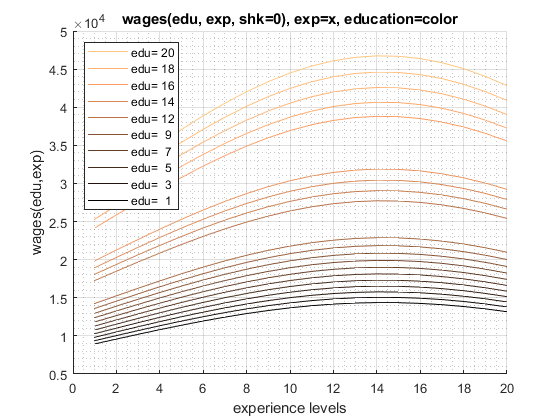

% 1 to 16 years of educations
ar_edu = 1:1:20;
% 1 to 20 years of experiences
ar_exp = 1:1:20;
% broadcast evaluate
mt_wages = f_wage(0,1,ar_edu',ar_exp,0);
% graph using MEconTools
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_graph_title') = {'wages(edu, exp, shk=0), exp=x, education=color'};
mp_support_graph('cl_st_ytitle') = {'wages(edu,exp)'};
mp_support_graph('cl_st_xtitle') = {'experience levels'};
mp_support_graph('bl_graph_logy') = false; % do not log
mp_support_graph('st_rowvar_name') = 'edu=';
mp_support_graph('it_legend_select') = 10; % how many shock legends to show
mp_support_graph('st_rounding') = '3.0f'; % format shock legend
mp_support_graph('cl_colors') = 'copper'; % any predefined matlab colormap
% Call function
ff_graph_grid(mt_wages, ar_edu, ar_exp, mp_support_graph);

### Wage Distribution with Shocks for Two Education and Experience Combinations

Draw the shock term from gamma distribution, distribution of wages at a particular experience and education combination with many shocks. 

% Gamma distribution parameters from Hai and Heckman
% E(epsilon) = a*b, var(epsion) = a*b^2.
a0 = 15.3558; % shape
b0 = 0.1388; % scale
% use gamrnd
it_draws = 10000;
ar_gamma_draws = gamrnd(a0, b0, [it_draws, 1]);
% Evaluate with 12 years of education and 10 years of experience with
% different shocks
ar_wages_e16_x10 = f_wage(0,1,16,10,ar_gamma_draws);
ar_wages_e12_x5 = f_wage(0,1,12,5,ar_gamma_draws);

Draw a histogram of the wage distribution. [Multiple histograms in matlab](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html).

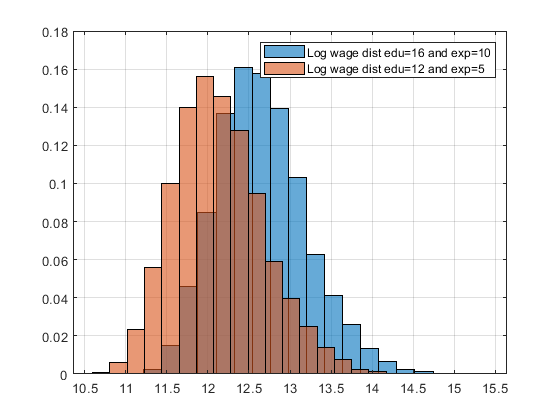

figure();
h1 = histogram(log(ar_wages_e16_x10), 20);
hold on;
h2 = histogram(log(ar_wages_e12_x5), 20);
grid on;
h1.Normalization = 'probability';
h2.Normalization = 'probability';
% Put up legend.
legend1 = sprintf('Log wage dist edu=16 and exp=10');
legend2 = sprintf('Log wage dist edu=12 and exp=5');
legend({legend1, legend2});

Generate distributional statistics using [FF_SIMU_STATS](https://fanwangecon.github.io/MEconTools/MEconTools/doc/stats/htmlpdfm/fx_simu_stats.html) from [MEconTools](https://fanwangecon.github.io/MEconTools/). Given that the shocks are the same, the distributional statistics in terms of gini, and shares of wages held by different percentiles are the same. However, 

% Set Parameters
mp_cl_mt_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
mp_cl_mt_xyz_of_s('cl_wages_e16_x10') = {ar_wages_e16_x10, zeros(1)};
mp_cl_mt_xyz_of_s('cl_ar_wages_e12_x5') = {ar_wages_e12_x5, zeros(1)};
mp_cl_mt_xyz_of_s('ar_st_y_name') = ["cl_wages_e16_x10", "cl_ar_wages_e12_x5"];
% Mass
rng(123);
mt_f_of_s = 1/it_draws + zeros(size(ar_wages_e16_x10));
% Call Function
mp_cl_mt_xyz_of_s_out = ff_simu_stats(mt_f_of_s, mp_cl_mt_xyz_of_s);

xxx tb_outcomes: all stats xxx
        OriginalVariableNames        cl_wages_e16_x10    cl_ar_wages_e12_x5
    _____________________________    ________________    __________________

    {'mean'                     }       3.7009e+05           2.2035e+05    
    {'unweighted_sum'           }       3.7009e+09           2.2035e+09    
    {'sd'                       }       2.5548e+05           1.5212e+05    
    {'coefofvar'                }          0.69034              0.69034    
    {'gini'                     }          0.31929              0.31929    
    {'min'                      }            72823                43359    
    {'max'                      }       4.1108e+06           2.4476e+06    
    {'pYis0'                    }                0                    0    
    {'pYls0'                    }                0                    0    
    {'pYgr0'                  